# Ejercicio 1. Y-Y 4 hilos desbalanceados

## Brayan Leonardo Maldonado Durán

## UIS - Sede Málaga - CIRCUITOS ELÉCTRICOS II

## Determine la potencia compleja transmitida a la carga trifásica de un circuito Y − Y de cuatro hilos como el que se muestra en la figure 1. Los voltajes de fasor de la fuente conectada en Y son Va = 120∠0◦ Vrms, Vb = 120∠ − 120◦ Vrms, y Vc = 120∠120◦ Vrms. Las impedancias de carga son ZA = 80 + j50 Ω, ZB = 80 + j80 Ω y ZC = 100 − j25 Ω.

clear; clc     % Limpiar el Workspace
deg = pi/180;  % Factor de grados -> radianes

## ---- Datos ----

% Tensiones de fase (L-N) en V_rms dadas en polares (Magnitud y Ángulo)
% (grados)
Va_mag = 120; Va_ang = 0; % Va = 120∠0◦
Vb_mag = 120; Vb_ang = -120; % Vb = 120∠ - 120◦
Vc_mag = 120; Vc_ang = 120; % Vc = 120∠120◦
% Impedancias de cargas por fases (Ω) -> Desbalanceadas
ZA=80 + 1j*50;    % ZA = 80 + j50 Ω
ZB=80 + 1j*80;    % ZB = 80 + j80 Ω 
ZC=100 - 1j*25;   % ZC = 100 − j25 Ω
plot_phasors = true; % Mostrar el diagrama fasorial de Corrientes

## ----- Construcción de Fasores -----

phasor = @(mag,ang_ded) mag .* exp(1j*ang_ded*deg)

phasor = function_handle with value:
    @(mag,ang_ded)mag.*exp(1j*ang_ded*deg)


Va = phasor(Va_mag, Va_ang);
Vb = phasor(Vb_mag, Vb_ang);
Vc = phasor(Vc_mag, Vc_ang);

## Calculos Eléctricos

% Y-Y con Neutro. Corriente de Linea = Corriente de Fase
IaA = Va / ZA; % Corriente IaA
IbB = Vb / ZB; % Corriente IbB
IcC = Vc / ZC; % Corriente IcC
% Calcular la corriente Neutro (LCK en el nodo neutro n)
InN = -(IaA + IbB + IcC);
% Potencias por fase ( Convención Pasiva S = V * conj(I)) la conjugada sólo
% es para 4 hilos
SA = Va * conj(IaA); % Potencia ZA
SB = Vb * conj(IbB); % Potencia ZB
SC = Vc * conj(IcC); % Potencia ZC
ST = SA + SB + SC; % Potencia Total
% Desglozar el resultado
P = real(ST); % Potencia Activa (W)
Q = imag(ST); % Potencia Reactiva (VAR)
Sabs = abs(ST); % Potencia Aparente (VA)
fp = P / max(Sabs, eps); % Factor de Potencia
fp_tipo = "Inductivo";
if fp < 0
    fp_tipo = "Capacitivo";
end

## ---- Salida de Datos ----

toPolar = @(x) [abs(x) rad2deg(angle(x))];  % Función Anónima: Convertir un numero complejo x=a + jb a forma polar
                                            % abs(x) = |x|, angle(x) = fase en radianers rad2deg pasa de radianes a grados
fmtPol = @(x) sprintf('%.4g ∠ %2f°', toPolar(x)); % Función anónima, toma x llama a la función toPolar(x) y devuelve 
                                                      % un texto con formato M ∠ θ. &.4g tome 4 cifras significativas para la magnitud
                                                      % %2f° tome dos decimales para el angulo
fmtRect = @(x) sprintf('%.4g %+.4gj', real(x), imag(x)); % Devuelvo un formato A + jB

% TENSIONES
disp('--- Tensiones de Fase (V_rms)'); % Encabezado

--- Tensiones de Fase (V_rms)


fprintf('Va = %s V\n', fmtPol(Va)); % Imprime el Va en formato M ∠ θ

Va = 120 ∠ 0.000000° V


fprintf('Vb = %s V\n', fmtPol(Vb)); % V/n Salto de 1 renglón

Vb = 120 ∠ -120.000000° V


fprintf('Vc = %s V\n\n', fmtPol(Vc)); % V/n/n Salto de doble renglon

Vc = 120 ∠ 120.000000° V




% IMPEDANCIAS
disp('--- Impedancias de Cargas (Ω) ---')           % Encabezado

--- Impedancias de Cargas (Ω) ---


fprintf('ZA = %.4g %+.4gj Ω\n', real(ZA), imag(ZA));   % Imprime ZA= a + jb

ZA = 80 +50j Ω


fprintf('ZB = %.4g %+.4gj Ω\n', real(ZB), imag(ZB)); 

ZB = 80 +80j Ω


fprintf('ZC = %.4g %+.4gj Ω\n\n', real(ZC), imag(ZC)); 

ZC = 100 -25j Ω




% CORRIENTES
disp('--- Corrientes de fase/linea (A_rms)');

--- Corrientes de fase/linea (A_rms)


fprintf('IaA = %s A | %s A (react)) \n', fmtPol(IaA), fmtRect(IaA));

IaA = 1.272 ∠ -32.005383° A | 1.079 -0.6742j A (react)) 


fprintf('IbB = %s A | %s A (react)\n', fmtPol(IbB), fmtRect(IbB));

IbB = 1.061 ∠ -165.000000° A | -1.025 -0.2745j A (react)


fprintf('IcC = %s A | %s A (react)\n', fmtPol(IcC), fmtRect(IcC));

IcC = 1.164 ∠ 134.036243° A | -0.8092 +0.8369j A (react)


fprintf('InN = %s A | %s A (react)\n\n', fmtPol(InN), fmtRect(InN));

InN = 0.7633 ∠ 8.418591° A | 0.7551 +0.1118j A (react)




% POTENCIAS
disp('---  Potencias ---')

---  Potencias ---


fprintf('SA = %s VA | %s VA (rect) \n', fmtPol(SA), fmtRect(SA));

SA = 152.6 ∠ 32.005383° VA | 129.4 +80.9j VA (rect) 


fprintf('SB = %s VA | %s VA (rect) \n', fmtPol(SB), fmtRect(SB));

SB = 127.3 ∠ 45.000000° VA | 90 +90j VA (rect) 


fprintf('SC = %s VA | %s VA (rect) \n', fmtPol(SC), fmtRect(SC));

SC = 139.7 ∠ -14.036243° VA | 135.5 -33.88j VA (rect) 


fprintf('ST = %s VA | %s VA (rect) \n\n', fmtPol(ST), fmtRect(ST));

ST = 380.5 ∠ 21.106451° VA | 355 +137j VA (rect) 



fprintf(' P = % 4g W \n', P);

 P =  354.968 W 


fprintf(' Q = %4g VAR (%s)\n', Q, fp_tipo);

 Q = 137.017 VAR (Inductivo)


fprintf(' |s| = %.4g VA \n', Sabs);

 |s| = 380.5 VA 


fprintf(' fp = %.4f (%s)\n', fp, fp_tipo)

 fp = 0.9329 (Inductivo)


## ---- DIAGRAMA FASORIAL ----

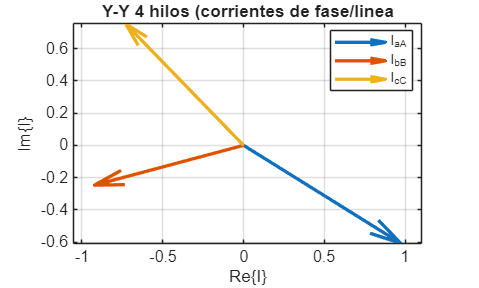

if plot_phasors
    figure('Name','Corrientes de fase/ linea'); % Vamos a crear una figura que se llamará fase/linea
    hold on; axis equal; grid on; box on;

    quiver(0,0, real(IaA), imag(IaA), 'LineWidth',2, 'MaxHeadSize',0.6);
    quiver(0,0, real(IbB), imag(IbB), 'LineWidth',2, 'MaxHeadSize',0.6);
    quiver(0,0, real(IcC), imag(IcC), 'LineWidth',2, 'MaxHeadSize',0.6);
    legend('I_{aA}', 'I_{bB}', 'I_{cC}', 'Location', 'best' );
    xlabel('Re\{I\}'); ylabel('Im\{I\}');
    title('Y-Y 4 hilos (corrientes de fase/linea');
end 

# EJERCICIO 2. Y-Y 4 Hilos Balanceado

## Brayan Leonardo Maldonado Durán

## UIS - Sede Málaga - CIRCUITOS ELÉCTRICOS II

## Determine la potencia compleja transmitida a la carga trifásica de un circuito Y − Y de cuatro hilos como el que se muestra en la figure 2. Los voltajes de fasorde la fuente conectada en Y son Va = 120∠0◦Vrms, Vb = 120∠ −120◦Vrms, y Vc = 120∠120◦Vrms. Las impedancias de carga son ZA = ZB = ZC = 40+j30Ω.

clear; clc;
deg = pi/180;

## ---- Datos ----

% Tensiones de fase (L-N) en V_rms dadas en polares (Magnitud y Ángulo)
% (grados)
Va_mag = 120; Va_ang = 0; % Va = 120∠0◦
Vb_mag = 120; Vb_ang = -120; % Vb = 120∠ - 120◦
Vc_mag = 120; Vc_ang = 120; % Vc = 120∠120◦
% Impedancias de cargas por fases (Ω) -> Balanceadas
ZA = 40 + 1j*30;
ZB = 40 + 1j*30;
ZC = 40 + 1j*30;
plot_phasors = true; % Mostrar el diagrama fasorial de Corrientes
 

## ----- Construcción de Fasores -----

phasor = @(mag,ang_ded) mag .* exp(1j*ang_ded*deg)

phasor = function_handle with value:
    @(mag,ang_ded)mag.*exp(1j*ang_ded*deg)


Va = phasor(Va_mag, Va_ang);
Vb = phasor(Vb_mag, Vb_ang);
Vc = phasor(Vc_mag, Vc_ang);

## Calculos Eléctricos

% Y-Y con Neutro. Corriente de Linea = Corriente de Fase
IaA = Va / ZA; % Corriente IaA
IbB = Vb / ZB; % Corriente IbB
IcC = Vc / ZC; % Corriente IcC
% Calcular la corriente Neutro (LCK en el nodo neutro n)
InN = -(IaA + IbB + IcC);
% Potencias por fase ( Convención Pasiva S = V * conj(I)) la conjugada sólo
% es para 4 hilos
SA = Va * conj(IaA); % Potencia ZA
SB = Vb * conj(IbB); % Potencia ZB
SC = Vc * conj(IcC); % Potencia ZC
ST = SA + SB + SC; % Potencia Total
% Desglozar el resultado
P = real(ST); % Potencia Activa (W)
Q = imag(ST); % Potencia Reactiva (VAR)
Sabs = abs(ST); % Potencia Aparente (VA)
fp = P / max(Sabs, eps); % Factor de Potencia
fp_tipo = "Inductivo";
if fp < 0
    fp_tipo = "Capacitivo";
end

## ---- Salida de Datos ----

toPolar = @(x) [abs(x) rad2deg(angle(x))];  % Función Anónima: Convertir un numero complejo x=a + jb a forma polar
                                            % abs(x) = |x|, angle(x) = fase en radianers rad2deg pasa de radianes a grados
fmtPol = @(x) sprintf('%.4g ∠ %2f°', toPolar(x)); % Función anónima, toma x llama a la función toPolar(x) y devuelve 
                                                      % un texto con formato M ∠ θ. &.4g tome 4 cifras significativas para la magnitud
                                                      % %2f° tome dos decimales para el angulo
fmtRect = @(x) sprintf('%.4g %+.4gj', real(x), imag(x)); % Devuelvo un formato A + jB

% TENSIONES
disp('--- Tensiones de Fase (V_rms)'); % Encabezado

--- Tensiones de Fase (V_rms)


fprintf('Va = %s V\n', fmtPol(Va)); % Imprime el Va en formato M ∠ θ

Va = 120 ∠ 0.000000° V


fprintf('Vb = %s V\n', fmtPol(Vb)); % V/n Salto de 1 renglón

Vb = 120 ∠ -120.000000° V


fprintf('Vc = %s V\n\n', fmtPol(Vc)); % V/n/n Salto de doble renglon

Vc = 120 ∠ 120.000000° V




% IMPEDANCIAS
disp('--- Impedancias de Cargas (Ω) ---')           % Encabezado

--- Impedancias de Cargas (Ω) ---


fprintf('ZA = %.4g %+.4gj Ω\n', real(ZA), imag(ZA));   % Imprime ZA= a + jb

ZA = 40 +30j Ω


fprintf('ZB = %.4g %+.4gj Ω\n', real(ZB), imag(ZB)); 

ZB = 40 +30j Ω


fprintf('ZC = %.4g %+.4gj Ω\n\n', real(ZC), imag(ZC)); 

ZC = 40 +30j Ω




% CORRIENTES
disp('--- Corrientes de fase/linea (A_rms)');

--- Corrientes de fase/linea (A_rms)


fprintf('IaA = %s A | %s A (react)) \n', fmtPol(IaA), fmtRect(IaA));

IaA = 2.4 ∠ -36.869898° A | 1.92 -1.44j A (react)) 


fprintf('IbB = %s A | %s A (react)\n', fmtPol(IbB), fmtRect(IbB));

IbB = 2.4 ∠ -156.869898° A | -2.207 -0.9428j A (react)


fprintf('IcC = %s A | %s A (react)\n', fmtPol(IcC), fmtRect(IcC));

IcC = 2.4 ∠ 83.130102° A | 0.2871 +2.383j A (react)


fprintf('InN = %s A | %s A (react)\n\n', fmtPol(InN), fmtRect(InN));

InN = 8.006e-16 ∠ 146.309932° A | -6.661e-16 +4.441e-16j A (react)




% POTENCIAS
disp('---  Potencias ---')

---  Potencias ---


fprintf('SA = %s VA | %s VA (rect) \n', fmtPol(SA), fmtRect(SA));

SA = 288 ∠ 36.869898° VA | 230.4 +172.8j VA (rect) 


fprintf('SB = %s VA | %s VA (rect) \n', fmtPol(SB), fmtRect(SB));

SB = 288 ∠ 36.869898° VA | 230.4 +172.8j VA (rect) 


fprintf('SC = %s VA | %s VA (rect) \n', fmtPol(SC), fmtRect(SC));

SC = 288 ∠ 36.869898° VA | 230.4 +172.8j VA (rect) 


fprintf('ST = %s VA | %s VA (rect) \n\n', fmtPol(ST), fmtRect(ST));

ST = 864 ∠ 36.869898° VA | 691.2 +518.4j VA (rect) 



fprintf(' P = % 4g W \n', P);

 P =  691.2 W 


fprintf(' Q = %4g VAR (%s)\n', Q, fp_tipo);

 Q = 518.4 VAR (Inductivo)


fprintf(' |s| = %.4g VA \n', Sabs);

 |s| = 864 VA 


fprintf(' fp = %.4f (%s)\n', fp, fp_tipo)

 fp = 0.8000 (Inductivo)


## ---- DIAGRAMA FASORIAL ----

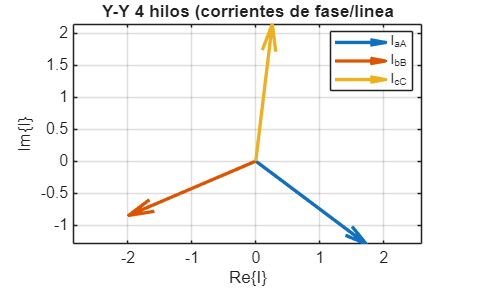

if plot_phasors
    figure('Name','Corrientes de fase/ linea'); % Vamos a crear una figura que se llamará fase/linea
    hold on; axis equal; grid on; box on;

    quiver(0,0, real(IaA), imag(IaA), 'LineWidth',2, 'MaxHeadSize',0.6);
    quiver(0,0, real(IbB), imag(IbB), 'LineWidth',2, 'MaxHeadSize',0.6);
    quiver(0,0, real(IcC), imag(IcC), 'LineWidth',2, 'MaxHeadSize',0.6);
    legend('I_{aA}', 'I_{bB}', 'I_{cC}', 'Location', 'best' );
    xlabel('Re\{I\}'); ylabel('Im\{I\}');
    title('Y-Y 4 hilos (corrientes de fase/linea');
end 

# Ejercicio 3. Y-Y 3 hilos desbalanceados

## Brayan Leonardo Maldonado Durán

## UIS - Sede Málaga - CIRCUITOS ELÉCTRICOS II

## Determine la potencia compleja transmitida a la carga trifásica de un circuito Y − Y de tres hilos como el que se muestra en la figure 3. Los voltajes de fasor de la fuente conectada en Y son Va = 120∠0◦Vrms, Vb = 120∠ −120◦Vrms, y Vc = 120∠120◦Vrms. Las impedancias de carga son ZA = 80 + j50Ω, ZB = 80 +j80Ω y ZC = 100−j25Ω.

clear; clc;
deg = pi/180;

## ---- Datos ----

Va_mag = 120; Va_ang = 0; % Va = 120∠0◦
Vb_mag = 120; Vb_ang = -120; % Vb = 120∠ - 120◦
Vc_mag = 120; Vc_ang = 120; % Vc = 120∠120◦
% Impedancias de cargas por fases (Ω) -> Desbalanceadas
ZA=80 + 1j*50;    % ZA = 80 + j50 Ω
ZB=80 + 1j*80;    % ZB = 80 + j80 Ω 
ZC=100 - 1j*25;   % ZC = 100 − j25 Ω
plot_phasors = true; % Mostrar el diagrama fasorial de Corrientes

## ----- Construcción de Fasores -----

phasor = @(mag,ang_ded) mag .* exp(1j*ang_ded*deg)

phasor = function_handle with value:
    @(mag,ang_ded)mag.*exp(1j*ang_ded*deg)


Va = phasor(Va_mag, Va_ang);
Vb = phasor(Vb_mag, Vb_ang);
Vc = phasor(Vc_mag, Vc_ang);

## --- CÁLCULOS ELÉCTRICOS ---

VNn = ((Va*ZB*ZC)+(Vb*ZA*ZC)+(Vc*ZA*ZB))/((ZB*ZC)+(ZA*ZC)+(ZA*ZB));
IaA = ((Va-VNn)/(ZA));
IbB = ((Vb-VNn)/(ZB));
IcC = ((Vc-VNn)/(ZC));
InN = -(IaA + IbB + IcC);


## --- POTENCIAS ---

SA = Va * conj(IaA);
SB = Vb * conj(IbB);
SC = Vc * conj(IcC);
ST = SA + SB + SC;
P = real(ST);
Q = imag(ST);
Sabs = abs(ST);
fp = P / max(Sabs, eps);
fp_tipo = "Inductivo";
if fp < 0
    fp_tipo = "Capacitivo";
end


## --- SALIDA FORMATEADA ---

toPolar = @(x)[abs(x) rad2deg(angle(x))];
fmtPol = @(x) sprintf ('%4g ∠ %2f°', toPolar(x));
fmtRect = @(x) sprintf ('%.4g %+.4gj', real(x), imag(x)); 

% TENSIONES
disp('--- Tensiones de Fase (V_rms)'); % Encabezado

--- Tensiones de Fase (V_rms)


fprintf('Va = %s V\n', fmtPol(Va)); % Imprime el Va en formato M ∠ θ

Va =  120 ∠ 0.000000° V


fprintf('Vb = %s V\n', fmtPol(Vb)); % V/n Salto de 1 renglón

Vb =  120 ∠ -120.000000° V


fprintf('Vc = %s V\n\n', fmtPol(Vc)); % V/n/n Salto de doble renglon

Vc =  120 ∠ 120.000000° V




% IMPEDANCIAS
disp('--- Impedancias de Cargas (Ω) ---')           % Encabezado

--- Impedancias de Cargas (Ω) ---


fprintf('ZA = %.4g %+.4gj Ω\n', real(ZA), imag(ZA));   % Imprime ZA= a + jb

ZA = 80 +50j Ω


fprintf('ZB = %.4g %+.4gj Ω\n', real(ZB), imag(ZB)); 

ZB = 80 +80j Ω


fprintf('ZC = %.4g %+.4gj Ω\n\n', real(ZC), imag(ZC)); 

ZC = 100 -25j Ω




% CORRIENTES
disp('--- Corrientes de fase/linea (A_rms)');

--- Corrientes de fase/linea (A_rms)


fprintf('IaA = %s A | %s A (react)) \n', fmtPol(IaA), fmtRect(IaA));

IaA = 1.54583 ∠ -26.403230° A | 1.385 -0.6874j A (react)) 


fprintf('IbB = %s A | %s A (react)\n', fmtPol(IbB), fmtRect(IbB));

IbB = 0.850512 ∠ -156.242112° A | -0.7784 -0.3426j A (react)


fprintf('IcC = %s A | %s A (react)\n', fmtPol(IcC), fmtRect(IcC));

IcC = 1.19517 ∠ 120.474997° A | -0.6061 +1.03j A (react)


fprintf('InN = %s A | %s A (react)\n\n', fmtPol(InN), fmtRect(InN));

InN =    0 ∠ 0.000000° A | -0 +0j A (react)




% POTENCIAS
disp('---  Potencias ---')

---  Potencias ---


fprintf('SA = %s VA | %s VA (rect) \n', fmtPol(SA), fmtRect(SA));

SA = 185.5 ∠ 26.403230° VA | 166.1 +82.49j VA (rect) 


fprintf('SB = %s VA | %s VA (rect) \n', fmtPol(SB), fmtRect(SB));

SB = 102.061 ∠ 36.242112° VA | 82.32 +60.34j VA (rect) 


fprintf('SC = %s VA | %s VA (rect) \n', fmtPol(SC), fmtRect(SC));

SC = 143.42 ∠ -0.474997° VA | 143.4 -1.189j VA (rect) 


fprintf('ST = %s VA | %s VA (rect) \n\n', fmtPol(ST), fmtRect(ST));

ST = 416.691 ∠ 19.871559° VA | 391.9 +141.6j VA (rect) 



fprintf(' P = % 4g W \n', P);

 P =  391.88 W 


fprintf(' Q = %4g VAR (%s)\n', Q, fp_tipo);

 Q = 141.639 VAR (Inductivo)


fprintf(' |s| = %.4g VA \n', Sabs);

 |s| = 416.7 VA 


fprintf(' fp = %.4f (%s)\n', fp, fp_tipo)

 fp = 0.9405 (Inductivo)


## ---- DIAGRAMA FASORIAL ----

I_bBQuiver =   Quiver (I_{bB}) with properties:

        Color: [0.8660 0.3290 0]
    LineStyle: '-'
    LineWidth: 2
        XData: 0
        YData: 0
        ZData: []
        UData: -0.7784
        VData: -0.3426
        WData: []

  Show all properties


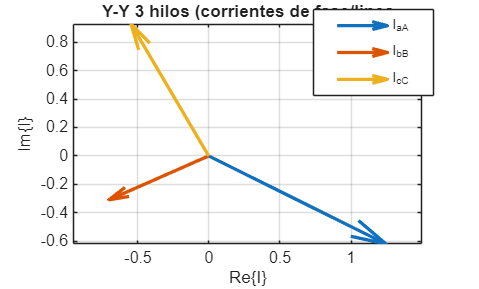

if plot_phasors
    figure('Name','Corrientes de fase/ linea'); % Vamos a crear una figura que se llamará fase/linea
    hold on; axis equal; grid on; box on;

    quiver(0,0, real(IaA), imag(IaA), 'LineWidth',2, 'MaxHeadSize',0.6);
    quiver(0,0, real(IbB), imag(IbB), 'LineWidth',2, 'MaxHeadSize',0.6);
    quiver(0,0, real(IcC), imag(IcC), 'LineWidth',2, 'MaxHeadSize',0.6);
    legend('I_{aA}', 'I_{bB}', 'I_{cC}', 'Location', 'best' );
    xlabel('Re\{I\}'); ylabel('Im\{I\}');
    title('Y-Y 3 hilos (corrientes de fase/linea');
    
xlim("auto")
ylim("auto")
 
I_bBQuiver = findobj(gcf, "DisplayName", "I_{bB}")
datatip(I_bBQuiver,0,0);

legend(["I_{aA}", "I_{bB}", "I_{cC}"], "Position", [0.6936 0.7164 0.1721, 0.2064])
end 

# EJERCICIO 4. Y-Y 3 hilos balanceados

## Brayan Leonardo Maldonado Durán

## UIS - Sede Málaga - CIRCUITOS ELÉCTRICOS II

## Determine la potencia compleja transmitida a la carga trifásica de un circuito Y − Y de tres hilos como el que se muestra en la figure 4. Los voltajes de fasor de la fuente conectada en Y son Va = 120∠0◦Vrms, Vb = 120∠ −120◦Vrms, y Vc = 120∠120◦Vrms. Las impedancias de carga son ZA = ZB = ZC = 40+j30Ω.

clear; clc;
deg = pi/180; 

## ---- Datos ----

% Tensiones de fase (L-N) en V_rms dadas en polares (Magnitud y Ángulo)
% (grados)
Va_mag = 120; Va_ang = 0; % Va = 120∠0◦
Vb_mag = 120; Vb_ang = -120; % Vb = 120∠ - 120◦
Vc_mag = 120; Vc_ang = 120; % Vc = 120∠120◦
% Impedancias de cargas por fases (Ω) -> Desbalanceadas
ZA=40 + 1j*30;    % ZA = 80 + j50 Ω
ZB=40 + 1j*30;    % ZB = 80 + j80 Ω 
ZC=40 + 1j*30;   % ZC = 100 − j25 Ω
plot_phasors = true; % Mostrar el diagrama fasorial de Corrientes

## ----- Construcción de Fasores -----

phasor = @(mag,ang_ded) mag .* exp(1j*ang_ded*deg)

phasor = function_handle with value:
    @(mag,ang_ded)mag.*exp(1j*ang_ded*deg)


Va = phasor(Va_mag, Va_ang);
Vb = phasor(Vb_mag, Vb_ang);
Vc = phasor(Vc_mag, Vc_ang);

## --- CÁLCULOS ELÉCTRICOS ---

VNn = ((Va*ZB*ZC)+(Vb*ZA*ZC)+(Vc*ZA*ZB))/((ZB*ZC)+(ZA*ZC)+(ZA*ZB));
IaA = ((Va-VNn)/(ZA));
IbB = ((Vb-VNn)/(ZB));
IcC = ((Vc-VNn)/(ZC));
InN = -(IaA + IbB + IcC);


## --- POTENCIAS ---

SA = Va * conj(IaA);
SB = Vb * conj(IbB);
SC = Vc * conj(IcC);
ST = SA + SB + SC;
P = real(ST);
Q = imag(ST);
Sabs = abs(ST);
fp = P / max(Sabs, eps);
fp_tipo = "Inductivo";
if fp < 0
    fp_tipo = "Capacitivo";
end


## --- SALIDA FORMATEADA ---

toPolar = @(x)[abs(x) rad2deg(angle(x))];
fmtPol = @(x) sprintf ('%4g ∠ %2f°', toPolar(x));
fmtRect = @(x) sprintf ('%.4g %+.4gj', real(x), imag(x)); 

% TENSIONES
disp('--- Tensiones de Fase (V_rms)'); % Encabezado

--- Tensiones de Fase (V_rms)


fprintf('Va = %s V\n', fmtPol(Va)); % Imprime el Va en formato M ∠ θ

Va =  120 ∠ 0.000000° V


fprintf('Vb = %s V\n', fmtPol(Vb)); % V/n Salto de 1 renglón

Vb =  120 ∠ -120.000000° V


fprintf('Vc = %s V\n\n', fmtPol(Vc)); % V/n/n Salto de doble renglon

Vc =  120 ∠ 120.000000° V




% IMPEDANCIAS
disp('--- Impedancias de Cargas (Ω) ---')           % Encabezado

--- Impedancias de Cargas (Ω) ---


fprintf('ZA = %.4g %+.4gj Ω\n', real(ZA), imag(ZA));   % Imprime ZA= a + jb

ZA = 40 +30j Ω


fprintf('ZB = %.4g %+.4gj Ω\n', real(ZB), imag(ZB)); 

ZB = 40 +30j Ω


fprintf('ZC = %.4g %+.4gj Ω\n\n', real(ZC), imag(ZC)); 

ZC = 40 +30j Ω




% CORRIENTES
disp('--- Corrientes de fase/linea (A_rms)');

--- Corrientes de fase/linea (A_rms)


fprintf('IaA = %s A | %s A (react)) \n', fmtPol(IaA), fmtRect(IaA));

IaA =  2.4 ∠ -36.869898° A | 1.92 -1.44j A (react)) 


fprintf('IbB = %s A | %s A (react)\n', fmtPol(IbB), fmtRect(IbB));

IbB =  2.4 ∠ -156.869898° A | -2.207 -0.9428j A (react)


fprintf('IcC = %s A | %s A (react)\n', fmtPol(IcC), fmtRect(IcC));

IcC =  2.4 ∠ 83.130102° A | 0.2871 +2.383j A (react)


fprintf('InN = %s A | %s A (react)\n\n', fmtPol(InN), fmtRect(InN));

InN = 4.96507e-16 ∠ -63.434949° A | 2.22e-16 -4.441e-16j A (react)




% POTENCIAS
disp('---  Potencias ---')

---  Potencias ---


fprintf('SA = %s VA | %s VA (rect) \n', fmtPol(SA), fmtRect(SA));

SA =  288 ∠ 36.869898° VA | 230.4 +172.8j VA (rect) 


fprintf('SB = %s VA | %s VA (rect) \n', fmtPol(SB), fmtRect(SB));

SB =  288 ∠ 36.869898° VA | 230.4 +172.8j VA (rect) 


fprintf('SC = %s VA | %s VA (rect) \n', fmtPol(SC), fmtRect(SC));

SC =  288 ∠ 36.869898° VA | 230.4 +172.8j VA (rect) 


fprintf('ST = %s VA | %s VA (rect) \n\n', fmtPol(ST), fmtRect(ST));

ST =  864 ∠ 36.869898° VA | 691.2 +518.4j VA (rect) 



fprintf(' P = % 4g W \n', P);

 P =  691.2 W 


fprintf(' Q = %4g VAR (%s)\n', Q, fp_tipo);

 Q = 518.4 VAR (Inductivo)


fprintf(' |s| = %.4g VA \n', Sabs);

 |s| = 864 VA 


fprintf(' fp = %.4f (%s)\n', fp, fp_tipo)

 fp = 0.8000 (Inductivo)


## ---- DIAGRAMA FASORIAL ----

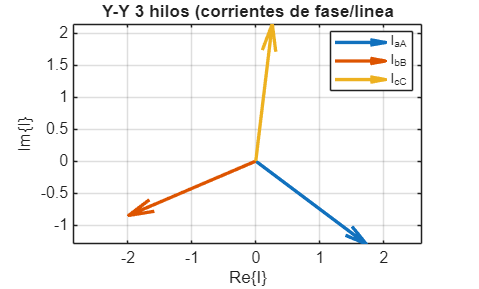

if plot_phasors
    figure('Name','Corrientes de fase/ linea'); % Vamos a crear una figura que se llamará fase/linea
    hold on; axis equal; grid on; box on;

    quiver(0,0, real(IaA), imag(IaA), 'LineWidth',2, 'MaxHeadSize',0.6);
    quiver(0,0, real(IbB), imag(IbB), 'LineWidth',2, 'MaxHeadSize',0.6);
    quiver(0,0, real(IcC), imag(IcC), 'LineWidth',2, 'MaxHeadSize',0.6);
    legend('I_{aA}', 'I_{bB}', 'I_{cC}', 'Location', 'best' );
    xlabel('Re\{I\}'); ylabel('Im\{I\}');
    title('Y-Y 3 hilos (corrientes de fase/linea');
end 

# EJERCICIO 5. Sistema Trifásico Y-Y 3 hilos balanceados con transformador

## Brayan Leonardo Maldonado Durán

## UIS - Sede Málaga - CIRCUITOS ELÉCTRICOS II

## Grafique el siguiente sistema trifásico Y − Y balanceado de tres hilos: Cada fase de la fuente conectada en Y esta dada por: 

## Va =100cos(377t)V 

## Vb = 100cos(377t +120◦)V

## Vc = 100cos(377t +240◦)V 

## Por fase, la linea tiene RL = 6Ω y LL = 3mH. La carga (por fase) es Rc = 24Ω en serie con Lc = 24mH 

## (a) Determine la corriente de línea por fase 

## (b) Halle el voltaje de fase en la carga VAN 

## (c) Calcule la potencia promedio:

##      • Suministrada por la fuente trifásica. 

##      • Absorbida por la línea 

##      • Entregada a la carga. 

## (d) Obtenga el factor de potencia y la eficiencia de transmisión

clear; clc;
deg = pi/180; 

## --- DATOS ---

% Para la Fuente
Vm = 100;              % Voltaje pico
W = 377;               % rad/s
f = W/(2*pi);          % Frecuencia

% Proporción para la fuente
Ps = 10;

% Impedancia de línea por fase
RL = 6;                % Ohm
LL = 3e-3;             % H
ZL = RL + 1j*W*LL;

% Impedancia de carga por fase
Rc = 24;                 % Ohm
Lc = (24e-3);            % H
Zc = Rc + 1j*W*Lc;

% Reflejo de la carga 10:1
Zcc = (10/1)^2 * Zc;

% Impedancia total en serie por fase (balanceado)
Zserie = ZL + Zcc;

% Fuente
Va_mag = (100*Ps); Va_ang = 0; 
Vb_mag = (100*Ps); Vb_ang = 120; 
Vc_mag = (100*Ps); Vc_ang = 240; 


## ----- Construcción de Fasores -----

phasor = @(mag,ang_ded) mag .* exp(1j*ang_ded*deg)

phasor = function_handle with value:
    @(mag,ang_ded)mag.*exp(1j*ang_ded*deg)


Va = phasor(Va_mag, Va_ang);
Vb = phasor(Vb_mag, Vb_ang);
Vc = phasor(Vc_mag, Vc_ang);

## (a) CORRIENTE DE LÍNEA POR FASE

IaA = Va / Zserie;
IbB = Vb / Zserie;
IcC = Vc / Zserie;

toPolar = @(x) [abs(x) rad2deg(angle(x))];  % Función Anónima: Convertir un numero complejo x=a + jb a forma polar
                                            % abs(x) = |x|, angle(x) = fase en radianers rad2deg pasa de radianes a grados
fmtPol = @(x) sprintf('%.4g ∠ %2f°', toPolar(x)); % Función anónima, toma x llama a la función toPolar(x) y devuelve 
                                                      % un texto con formato M ∠ θ. &.4g tome 4 cifras significativas para la magnitud
                                                      % %2f° tome dos decimales para el angulo
fmtRect = @(x) sprintf('%.4g %+.4gj', real(x), imag(x)); % Devuelvo un formato A + jB

disp('--- Corrientes de linea por fase (A_rms) ---');

--- Corrientes de linea por fase (A_rms) ---


fprintf('IaA = %s A | %s A (react)) \n', fmtPol(IaA), fmtRect(IaA));

IaA = 0.389 ∠ -20.632858° A | 0.364 -0.1371j A (react)) 


fprintf('IbB = %s A | %s A (react)\n', fmtPol(IbB), fmtRect(IbB));

IbB = 0.389 ∠ 99.367142° A | -0.06331 +0.3838j A (react)


fprintf('IcC = %s A | %s A (react)\n', fmtPol(IcC), fmtRect(IcC));

IcC = 0.389 ∠ -140.632858° A | -0.3007 -0.2467j A (react)



% Corriente en Fuente
Ia = (Ps) * IaA;
Ib = (Ps) * IbB;
Ic = (Ps) * IcC;

% Corriente en Carga
IA = (-Ps) * (-IaA);
IB = (-Ps) * (-IbB);
IC = (-Ps) * (-IcC);


## (b) VOLTAJE EN LA CARGA VAN

VAN_carga = IA * Zcc;

toPolar = @(x) [abs(x) rad2deg(angle(x))];  % Función Anónima: Convertir un numero complejo x=a + jb a forma polar
                                            % abs(x) = |x|, angle(x) = fase en radianers rad2deg pasa de radianes a grados
fmtPol = @(x) sprintf('%.4g ∠ %2f°', toPolar(x)); % Función anónima, toma x llama a la función toPolar(x) y devuelve 
                                                      % un texto con formato M ∠ θ. &.4g tome 4 cifras significativas para la magnitud
                                                      % %2f° tome dos decimales para el angulo
fmtRect = @(x) sprintf('%.4g %+.4gj', real(x), imag(x)); % Devuelvo un formato A + jB


disp('Voltaje de fase en la carga VAN (V RMS):')

Voltaje de fase en la carga VAN (V RMS):


fprintf('VAN = %s V\n', fmtPol(VAN_carga), fmtRect(VAN_carga));

VAN = 9977 ∠ 0.023585° V
VAN = 9977 +4.107j V


## (c) POTENCIAS


% Potencia absorbida por la línea
SaL = ((abs(IaA))^2 * RL)/2

SaL = 0.4539

SatotalL = 3 * SaL;  % Potencia total absorbida por la línea
disp('Potencia absorbida por la linea trifásica: \n')

Potencia absorbida por la linea trifásica: \n


SatotalL

SatotalL = 1.3617


% Potencia entregada a la carga
Sac = ((abs(IA))^2 * Rc) / 2

Sac = 181.5556

Satotalc = 3 * Sac;  % Potencia total entregada a la carga
disp('Potencia entrega a la carga trifásica: ')

Potencia entrega a la carga trifásica: 


Satotalc

Satotalc = 544.6667


% Potencia total suministrada por la fuente trifásica
Ss = SaL + Sac;
Sstotal = 3 * Ss;
disp('Potencia total suministrada por la fuente trifásica: ')

Potencia total suministrada por la fuente trifásica: 


Sstotal

Sstotal = 546.0283

disp('Potencia total suministrada por una fuente: ')

Potencia total suministrada por una fuente: 


Ss

Ss = 182.0094

## (d) FACTOR DE POTENCIA Y EFICIENCIA

FP = cos(angle(Sstotal));

P_fuente = real(Sstotal);
P_carga = real(Satotalc);

eficiencia = (P_carga / P_fuente) * 100;

disp('Factor de potencia:')

Factor de potencia:


FP

FP = 1


disp('Eficiencia de transmisión (%):')

Eficiencia de transmisión (%):


eficiencia

eficiencia = 99.7506

## GRÁFICA DEL SISTEMA TRIFÁSICO

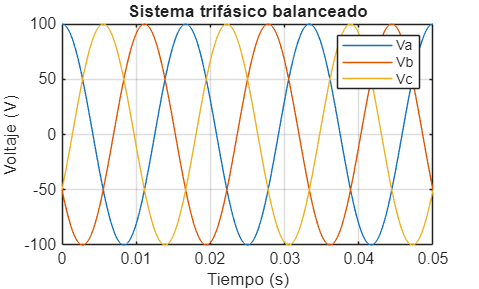

t = linspace(0, 3/f, 1000);

va_t = Vm*cos(W*t);
vb_t = Vm*cos(W*t + 2*pi/3);
vc_t = Vm*cos(W*t + 4*pi/3);

figure;
plot(t, va_t);
hold on;
plot(t, vb_t);
plot(t, vc_t);
grid on;
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Sistema trifásico balanceado');
legend('Va','Vb','Vc');